# **IBMs for Rapid Prototyping - Post Processing**

For processing exported data

#### Load simDataStore.m file:

addpath(genpath(pwd))
loadedFile = "C:\Users\georg\OneDrive - Loughborough University\_Y4\FYP\TEST RESULTS\all the results from LINUX\VENKAT results\resolution study\Mid\CORRECT SETTLING TIME\VI\save_2026-05-06_22-28-12\SimulationData_2026-05-06_22-28-12.mat"

loadedFile = "C:\Users\georg\OneDrive - Loughborough University\_Y4\FYP\TEST RESULTS\all the results from LINUX\VENKAT results\resolution study\Mid\CORRECT SETTLING TIME\VI\save_2026-05-06_22-28-12\SimulationData_2026-05-06_22-28-12.mat"

load(loadedFile);
finalPhysTime = simdataVariable.time(end)

finalPhysTime = 2.0000

fieldType = "Post Transient";
U = cat(3, simdataVariable.density, simdataVariable.xVelocity, simdataVariable.yVelocity, simdataVariable.pressure);
[X, Y] = deal(simdataVariable.meshGridXY(:,:,1), simdataVariable.meshGridXY(:,:,2));
[Ny, Nx] = size(X);
if fieldType == "Post Transient"
    Uavg = simdataVariable.fieldAvgPostTransient;
    switch Nx
        case {640, 480}
            settlingTime = 1
        case 320
            settlingTime = 1.5
        case 240
            settlingTime = 2
        otherwise
            error("Resolution not matched to standard test size")
    end
    avgTime = finalPhysTime - settlingTime;
    [~, avgStartIdx] = min(abs(simdataVariable.time - settlingTime));
    avgCount = length(simdataVariable.time) - avgStartIdx;
elseif fieldType == "Full"
    Uavg = simdataVariable.fieldAvg;
    avgTime = finalPhysTime;
    avgStartIdx = 1;
    avgCount = length(simdataVariable.time);
end

settlingTime = 1

plots = true;
[rho, u, v, p] = deal(U(:,:,1), U(:,:,2), U(:,:,3), U(:,:,4));
[rho_avg, u_avg, v_avg, p_avg] = deal(Uavg(:,:,1)/avgCount, Uavg(:,:,2)/avgCount, Uavg(:,:,3)/avgCount, Uavg(:,:,4)/avgCount);
[xGeo, yGeo]  = deal(simdataVariable.geometryData.XYGeometry(:,1), simdataVariable.geometryData.XYGeometry(:,2));
[rho0, U0, V0, p0] = deal(simdataVariable.freestreamConditions(1), simdataVariable.freestreamConditions(2), simdataVariable.freestreamConditions(3), simdataVariable.freestreamConditions(4));
CdAvg = mean(simdataVariable.coefficients(avgStartIdx:end,1))

CdAvg = 1.3636

ClAvg = mean(simdataVariable.coefficients(avgStartIdx:end,2))

ClAvg = -0.0075

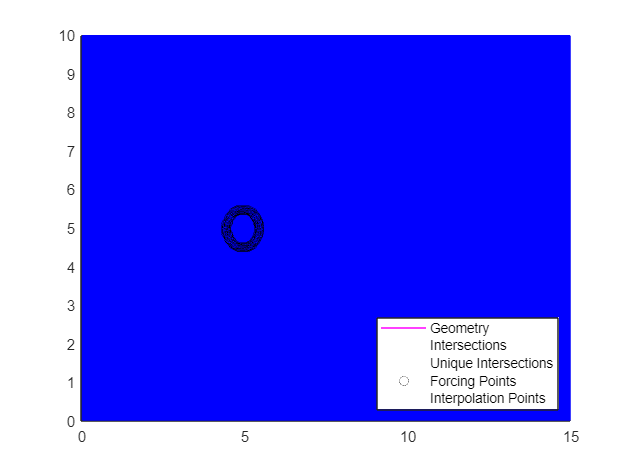

Re = rho0 * U0 * 1/0.0084035;
dx = X(1,1) - X(1,2);
dy = dx;

gridInterpretation = true;
geoObj = geometry(X, Y, xGeo, yGeo);
if gridInterpretation
geoObj = gridInterpret(xGeo, yGeo, geoObj.XGrid(1,:), geoObj.YGrid(:,1), geoObj);
uniqueIntersectX = geoObj.forcingMask(:,1,1);
uniqueIntersectY = geoObj.forcingMask(:,2,1);
cellNeighborXidx_filtered = geoObj.forcingMask(:,1,2);
cellNeighborYidx_filtered = geoObj.forcingMask(:,2,2);
interpCellIdxX = geoObj.forcingMask(:,1,3);
interpCellIdxY = geoObj.forcingMask(:,2,3);
globalNormIsect = geoObj.forcingMask(:,:,4);

XGridUnique = unique(geoObj.XGrid);
YGridUnique = unique(geoObj.YGrid);

cellNeighborXCoord = XGridUnique(cellNeighborXidx_filtered);
cellNeighborYCoord = YGridUnique(cellNeighborYidx_filtered);
interpCellXCoord = XGridUnique(interpCellIdxX);
interpCellYCoord = YGridUnique(interpCellIdxY);
end

VFWplots = false;
if VFWplots
geoObj = volumeFractions(geoObj.XYGeometry(:,1), geoObj.XYGeometry(:,2), geoObj.XGrid(1,:), geoObj.YGrid(:,1), geoObj);
imagesc(X(1,:), Y(:,1), geoObj.forcingMask);
colormap("gray")
axis equal tight;
axis xy; % IMPORTANT: flips y-direction to normal Cartesian

hold on;
plot(xGeo, yGeo, 'r', 'LineWidth', 1.5);
hold off;
end

NIplots = false;
if NIplots
imagesc(X(1,:), Y(:,1), geoObj.geometryCells);
colormap("gray")
axis equal tight;
axis xy; % IMPORTANT: flips y-direction to normal Cartesian

hold on;
plot(xGeo, yGeo, 'r', 'LineWidth', 1.5);
hold off;
end

#### **FFT **

% Preprocessing
t = simdataVariable.time;
CL = simdataVariable.coefficients(:,2)';

mask = t >= settlingTime;
t = t(mask);
CL = CL(mask);

% Ensure uniform timestep
dt = mean(diff(t));
fs = 1/dt;
N = length(CL);

% Remove mean
CL = CL - mean(CL);

% - Initial guess using FFT -
Yfft = fft(CL);
P = abs(Yfft/N);
P = P(1:floor(N/2));
f = (0:floor(N/2)-1)*(fs/N); % build frequency axis
[~, idx] = max(P);
f0 = f(idx);   % initial peak frequency guess

% Sine model
model = @(p, t) p(1)*sin(2*pi*p(2)*t + p(3)) + p(4);
% x(t) = A * sin(2*pi*f*t + phi) + C

% Initial parameter guess:
A0 = (max(CL)-min(CL))/2; % guess peak-to-peak value from CL min/max
phi0 = 0;
C0 = 0; % assume 0 from mean removal

p0 = [A0, f0, phi0, C0]; % p = [A, f, phi, C]

% Fit
opts = optimoptions('lsqcurvefit','Display','off');
t = t - t(1); % normalise time (can cause conditioning problems)
p_fit = lsqcurvefit(model, p0, t, CL, [], [], opts);

A = p_fit(1);
f_shedding = p_fit(2);
phi = p_fit(3);
C = p_fit(4);

% Output
fprintf('Shedding frequency = %.2f Hz\n', f_shedding);

Shedding frequency = 10.86 Hz


fprintf('Strouhal Number = %.4f\n', ...
    f_shedding / simdataVariable.freestreamConditions(2));

Strouhal Number = 0.1584


% df = fs/N;
% fprintf('Frequency resolution = %.4f Hz\n', df);
checkFit = false;
if checkFit
% ===== Reconstruct fitted signal =====
t_fit = t(:);

CL_fit = p_fit(1)*sin(2*pi*p_fit(2)*t_fit + p_fit(3)) + p_fit(4);

% ===== Plot =====
figure;
plot(t_fit, CL, 'k', 'DisplayName', 'Actual data');
hold on;
plot(t_fit, CL_fit, 'r--', 'LineWidth', 2, 'DisplayName', 'Fitted sine');

xlabel('Time (s)');
ylabel('C_L');
title('Sine Fit vs Actual Signal');
legend;
grid on;
hold off
end
% GROWTH PHASE DETECTION
t = simdataVariable.time;
CL = simdataVariable.coefficients(:,2)';

% apply settling cut first if needed 
% mask = t >= settlingTime;
% t = t(mask);
% CL = CL(mask);

%  ensure column vectors 
t = t(:);
CL = CL(:);

% preprocessing
CL = detrend(CL);
t = t - t(1); 

dt = mean(diff(t));

% envelope via Hilbert transform
A = abs(hilbert(CL));

% smooth envelope
A = smoothdata(A,'movmean',100);

%  estimate noise floor from early signal 
Nnoise = min(1000, round(0.1*length(A))); % first 10% or 1000 samples
noiseLevel = median(A(1:Nnoise));

%  growth onset threshold 
k_noise = 5; % sensitivity factor
thr_onset = k_noise * noiseLevel;

idx_onset = find(A > thr_onset, 1, 'first');
if isempty(idx_onset)
    % warning('No clear growth onset detected.');
    t_onset = NaN;
else
    t_onset = t(idx_onset);
end

%  estimate final amplitude from last portion 
Nsteady = min(10000, round(0.1*length(A)));
A_final = mean(A(end-Nsteady:end));

thr_sat = 0.95 * A_final;

%  require sustained saturation 
window_sat = 2000;  % adjust depending on sampling rate

idx_sat = NaN;
t_min = 0; %settlingTime;  % minimum for clamping results (use plot to determine)
idx_min = find(t >= t_min, 1, 'first');

for k = 1:(length(A) - window_sat)
    segment = A(k:k+window_sat);

    if all(segment > thr_sat)
        idx_sat = k;
        if idx_sat > idx_min
        break
        end
    end
end

if isnan(idx_sat)
    warning('No sustained saturation detected.');
else
    t_sat = t(idx_sat);
end

%  outputs 
fprintf('Saturation time : %.4f s\n', t_sat);

Saturation time : 1.1413 s


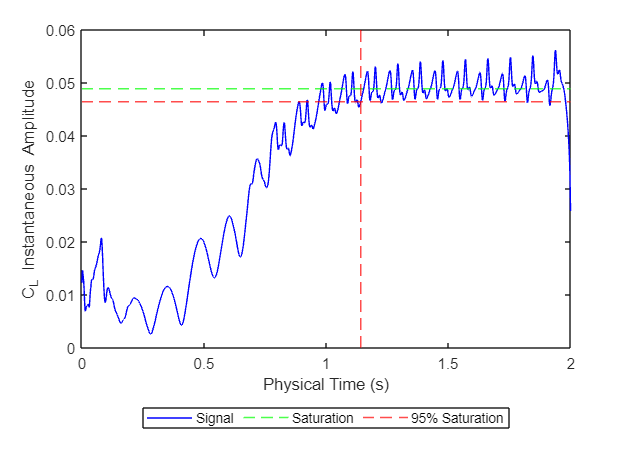

%  optional visualization 
if plots
plot(t, A, 'b'); hold on
yline(A_final,'g--', LineWidth=1);
yline(thr_sat,'r--', LineWidth=1);
if ~isnan(t_sat), xline(t_sat,'r--', LineWidth=1); end
xlabel('Physical Time (s)'); ylabel('C_L Instantaneous Amplitude') % instantaneous lift coefficient envelope
leg = legend('Signal','Saturation','95% Saturation','Location','southoutside','NumColumns',3);
end

#### Interpolate current Field:

% Lx = max(X,[],'all'); Ly = max(Y,[],'all');    % domain size
% [Ny, Nx] = size(X);
% usFactor = 1500/Nx;
% 
% Ny = Ny * usFactor; Nx = Nx * usFactor; 
% dx = Lx / Nx; dy = Ly / Ny; % grid spacing (x,y)
% x = linspace(dx/2, Lx-dx/2, Nx);
% y = linspace(dy/2, Ly-dy/2, Ny);
% [interpolatedGridX, interpolatedGridY] = meshgrid(x, y);
% 
% rho = interp2(X, Y, rho, interpolatedGridX, interpolatedGridY);
% u = interp2(X, Y, u, interpolatedGridX, interpolatedGridY);
% v = interp2(X, Y, v, interpolatedGridX, interpolatedGridY);
% p = interp2(X, Y, p, interpolatedGridX, interpolatedGridY);
% 
% X = interpolatedGridX;
% Y = interpolatedGridY;
% fprintf('Upscaling Factor: %.2f\n', usFactor);
% fprintf('Upscaling Resolution: %.0f x %.0f\n', Nx, Ny);

#### Visualise Flow:

param = "Velocity Magnitude"

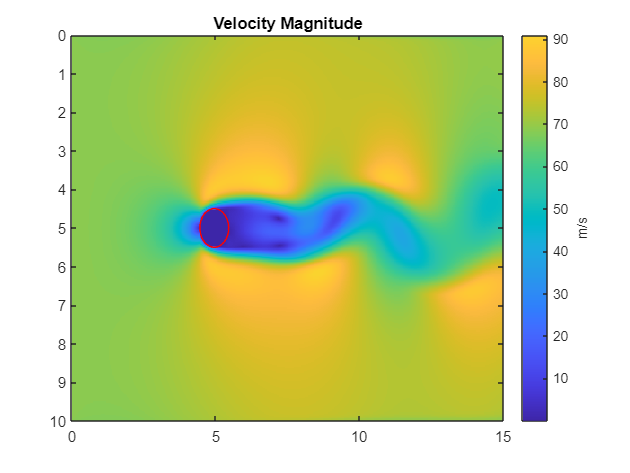

flowVisualisation = true;
if flowVisualisation
param = "Velocity Magnitude"
x = X(1,:);
y = Y(:,1);
gamma = 1.4;            % ratio of specific heats
R = 287;                % gas constant (not used explicitly if using p=(gamma-1)*rho*e)
switch param % TODO - check all the units are correct here
    case "Density"
        dataToDisplay = rho;
        colourbarLabel = "kg/m^3";
    case "X Velocity"
        dataToDisplay = u;
        colourbarLabel = "m/s";
    case "Y Velocity"
        dataToDisplay = v;
        colourbarLabel = "m/s";
    case "Pressure"
        dataToDisplay = p;
        colourbarLabel = "Pa";
    case {"Velocity Magnitude", "Mach", "Temperature"} % derived variables
        % derive parameters
        velocityMag = sqrt(u.^2 + v.^2);
        c = sqrt(max((gamma .* p) ./ rho, 1e-12));
        if param == "Velocity Magnitude"
            dataToDisplay = velocityMag;
            colourbarLabel = "m/s";
        elseif param == "Mach"
            dataToDisplay = velocityMag./c;
            colourbarLabel = "";
        else % temperature
            dataToDisplay = p./(rho.*R);
            colourbarLabel = "K";
        end
end

imageSizeX = [x(1) x(end)];
imageSizeY = [y(1) y(end)];
fig = figure;
flowFieldPlot = imagesc(imageSizeX, imageSizeY, dataToDisplay);
colourmap = parula;
colormap(colourmap(1:230,:))
title(fig.CurrentAxes, sprintf('%s', param));
colourbar = colorbar(fig.CurrentAxes);
colourbar.Label.String = colourbarLabel;
hold(fig.CurrentAxes, "on");
plot(fig.CurrentAxes, xGeo, yGeo, "r", LineWidth=1);
hold(fig.CurrentAxes, "off");

% if param == "Velocity Magnitude"
%     [dUmag_dx, dUmag_dy] = gradient(velocityMag, dx, dy);
%     gradMag = sqrt(dUmag_dx.^2 + dUmag_dy.^2);
%     fig = figure;
%     flowFieldPlot = imagesc(imageSizeX, imageSizeY, abs(dUmag_dx));
%     colourmap = parula;
%     colormap(colourmap(1:230,:))
%     title(fig.CurrentAxes, sprintf('X Direction Velocity Magnitude Gradients'));
%     colourbar = colorbar(fig.CurrentAxes);
%     colourbar.Label.String = colourbarLabel;
%     hold(fig.CurrentAxes, "on");
%     plot(fig.CurrentAxes, xGeo, yGeo, "r", LineWidth=1);
%     hold(fig.CurrentAxes, "off");
% 
%     fig = figure;
%     quiver(X, Y, dUmag_dx, dUmag_dy);
%     hold(fig.CurrentAxes, "on");
%     quiver(X, Y, u, v, "Color","r");
%     axis equal tight;
%     title('Velocity gradient vector field');
%     plot(fig.CurrentAxes, xGeo, yGeo, "r", LineWidth=1);
%     hold(fig.CurrentAxes, "off");
%     gridlines = true;
%     if gridlines
%         xticks(unique(X(1,:))); %#ok
%         yticks(unique(Y(:,1)));
%         set(gca,'YTickLabel',[]);
%         set(gca,'XTickLabel',[]);
%     end
%     grid on;
% 
%     legend("Gradients", "Velocity")
% 
% end

end

#### Interpolate Field:

% Lx = max(X,[],'all'); Ly = max(Y,[],'all');    % domain size
% [Ny, Nx] = size(X);
% usFactor = 5; %1500/Nx;
% 
% Ny = Ny * usFactor; Nx = Nx * usFactor; 
% dx = Lx / Nx; dy = Ly / Ny; % grid spacing (x,y)
% x = linspace(dx/2, Lx-dx/2, Nx);
% y = linspace(dy/2, Ly-dy/2, Ny);
% [interpolatedGridX, interpolatedGridY] = meshgrid(x, y);
% 
% rho_avg = interp2(X, Y, rho_avg, interpolatedGridX, interpolatedGridY);
% u_avg = interp2(X, Y, u_avg, interpolatedGridX, interpolatedGridY);
% v_avg = interp2(X, Y, v_avg, interpolatedGridX, interpolatedGridY);
% p_avg = interp2(X, Y, p_avg, interpolatedGridX, interpolatedGridY);
% 
% X = interpolatedGridX;
% Y = interpolatedGridY;
% fprintf('Upscaling Factor: %.2f\n', usFactor);
% fprintf('Upscaling Resolution: %.0f x %.0f\n', Nx, Ny);

#### Force Coefficients:

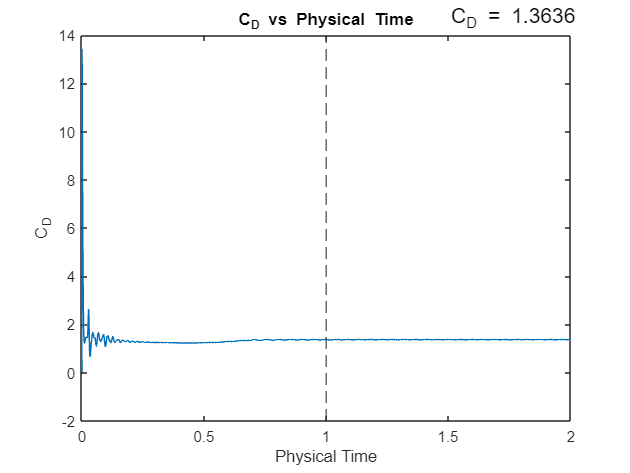

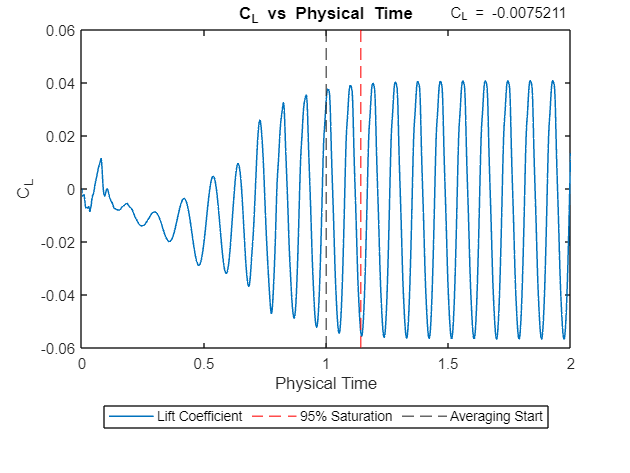

if plots
    figure
    plot(simdataVariable.time,simdataVariable.coefficients(:,1), LineWidth=1)
    hold on
    title("C_D vs Physical Time")
    xlabel("Physical Time")
    ylabel("C_D")
    annotation('textbox',[.7 .8 .4 .2], ...
        'String',['C_D = ' num2str(CdAvg)],'EdgeColor','none','FontSize',14)
    xline(settlingTime, "--", LineWidth=1);
    hold off
    figure
    plot(simdataVariable.time,simdataVariable.coefficients(:,2), LineWidth=1)
    hold on
    title("C_L vs Physical Time")
    xlabel("Physical Time")
    ylabel("C_L")
    annotation('textbox',[.7 .8 .4 .2], ...
        'String',['C_L = ' num2str(ClAvg)],'EdgeColor','none')
    if ~isnan(t_sat), xline(t_sat,'r--', LineWidth=1); end 
    xline(settlingTime, "--", LineWidth=1);
    leg = legend('Lift Coefficient','95% Saturation','Averaging Start','Location','southoutside','NumColumns',3);
    hold off
end

#### Boundary Location:

% find low velocity contour (approx. boundary location)

% user input
levelFactors = 0.001:0.001:0.02;
nInterp = 1000;        % number of interpolation points

% velocities
velocityMag = sqrt(u_avg.^2 + v_avg.^2);

rmse = zeros(size(levelFactors));
bestContours = cell(size(levelFactors));

for RMSEidx = 1:length(levelFactors)

    level = levelFactors(RMSEidx) * U0;

    % get contours
    fig = figure('Visible','off');
    ax = axes(fig); %#ok
    C = contour(ax, X, Y, velocityMag, [level level]);
    xlim([min(xGeo)*0.75 max(xGeo)*1.25]);
    ylim([min(yGeo)*0.75 max(yGeo)*1.25]);

    % parametrise true geometry
    tGeo = linspace(0,1,length(xGeo));
    tCommon = linspace(0,1,nInterp);

    xGeo_i = interp1(tGeo, xGeo, tCommon, 'linear');
    yGeo_i = interp1(tGeo, yGeo, tCommon, 'linear');

    % initialise
    idx = 1;
    best_rmse = inf;

    % loop through contour segments
    while idx < size(C,2)

        % Number of points in this segment
        nPoints = C(2,idx);

        % Extract this contour segment
        xB = C(1, idx+1:idx+nPoints)';
        yB = C(2, idx+1:idx+nPoints)';

        % Skip very small segments (noise)
        if nPoints < 20
            idx = idx + nPoints + 1;
            continue
        end

        % Parameterize contour
        tB = linspace(0,1,length(xB));

        % Interpolate contour
        xB_i = interp1(tB, xB, tCommon, 'linear');
        yB_i = interp1(tB, yB, tCommon, 'linear');

        % Compute pairwise distances
        D = pdist2([xGeo_i(:), yGeo_i(:)], [xB_i(:), yB_i(:)]);

        % For each geometry point, find closest contour point
        minDist = min(D, [], 2);

        % RMSE
        val = sqrt(mean(minDist.^2));

        min_rmse_segment = val;

        % Store best RMSE across all segments
        if min_rmse_segment < best_rmse
            best_rmse = min_rmse_segment;

            % Store best matching contour for plotting
            best_xB = xB_i;
            best_yB = yB_i;
        end

        % Move to next contour segment
        idx = idx + nPoints + 1;
    end

    %%  FINAL RESULT 
    rmse(RMSEidx) = best_rmse;

    bestContours{RMSEidx}.x = best_xB;
    bestContours{RMSEidx}.y = best_yB;

    close(fig)
end

[minRMSE, bestIdx] = min(rmse);
avgRMSE = mean(rmse);
fprintf('Average RMSE = %.3g%%\n', avgRMSE*100);

Average RMSE = 4.79%



optimalThreshold = levelFactors(bestIdx);

bestContour = bestContours{bestIdx};

fprintf('Final RMSE = %.4g\n', minRMSE);

Final RMSE = 0.02421


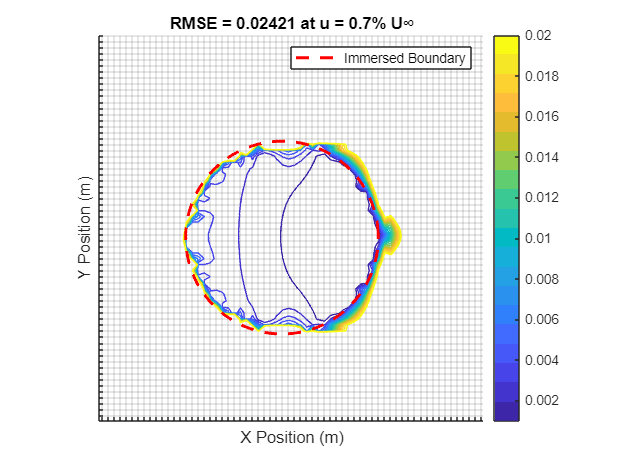


%%  PLOT FOR VERIFICATION 
figure;
hold on;
colourMap = parula(length(bestContours));
for i = 1:length(bestContours)
    currentColour = colourMap(i,:);
    plot(bestContours{i}.x, bestContours{i}.y, 'Color', currentColour, 'LineWidth', 1);
end
colormap(parula(length(bestContours)));
caxis([levelFactors(1) levelFactors(end)]);
cb = colorbar;
axis equal
title(sprintf('RMSE = %.4g at u = %.1f%% U∞', ...
      minRMSE, optimalThreshold*100));
xlabel('X Position (m)');
ylabel('Y Position (m)');

xlim([min(xGeo)*0.9 max(xGeo)*1.1]);
ylim([min(yGeo)*0.9 max(yGeo)*1.1]);
trueGeoHandle = plot(xGeo_i, yGeo_i, 'r--', 'LineWidth', 2); 
legend(trueGeoHandle, 'Immersed Boundary');

gridlines = true; 
if gridlines 
    xticks(unique(X(1,:))); %#ok
    yticks(unique(Y(:,1)));
    set(gca,'YTickLabel',[]);
    set(gca,'XTickLabel',[]);
end
grid on; 
hold off;


% figure;
% plot(levelFactors, rmse, 'LineWidth', 1.5);
% 
% xlabel('Threshold Velocity / U_\infty');
% ylabel('RMSE');
% grid on;
% % Highlight best point
% hold on
% % Find minimum RMSE point
% bestThreshold = levelFactors(bestIdx);
% plot(bestThreshold, minRMSE, 'ro', ...
%     'MarkerSize', 8, ...
%     'LineWidth', 1.5);
% 
% % Annotate
% text(bestThreshold, minRMSE+0.025, ...
%     sprintf('  Min RMSE = %.4f\n  Threshold = %.3f U_\\infty', ...
%     minRMSE, bestThreshold), ...
%     'VerticalAlignment', 'bottom');

#### Velocity at the boundary:

%  IBM BOUNDARY VELOCITY ENFORCEMENT CHECK (NO-SLIP ERROR)
nProbe = 400;

% parameterise geometry (assumed closed loop)
tGeo = linspace(0,1,length(xGeo));
t = linspace(0,1,nProbe);

xB = interp1(tGeo, xGeo, t, 'linear');
yB = interp1(tGeo, yGeo, t, 'linear');

% interpolate velocity onto boundary
uB = interp2(X, Y, u_avg, xB, yB, 'linear');
vB = interp2(X, Y, v_avg, xB, yB, 'linear');

% velocity magnitude (slip velocity)
Ub_mag = sqrt(uB.^2 + vB.^2);

% RMSE of no-slip condition (should be 0 ideally)
slip_RMSE = sqrt(mean(Ub_mag.^2));

fprintf('Boundary slip velocity RMSE = %.2f%% of U_inf\n', slip_RMSE/U0*100);

Boundary slip velocity RMSE = 2.47% of U_inf


% %  SPLIT TOP / BOTTOM + PLOT vs X-LOCATION
% mid = round(nProbe/2);
% midXLoc = xB(mid/2);
% 
% xTop = xB(1:mid);   yTop = yB(1:mid);
% xBot = xB(mid:end); yBot = yB(mid:end);
% 
% % interpolate velocity
% uTop = interp2(X, Y, u_avg, xTop, yTop);
% vTop = interp2(X, Y, v_avg, xTop, yTop);
% 
% uBot = interp2(X, Y, u_avg, xBot, yBot);
% vBot = interp2(X, Y, v_avg, xBot, yBot);
% 
% Utop = sqrt(uTop.^2 + vTop.^2);
% Ubot = sqrt(uBot.^2 + vBot.^2);
% 
% % sort by x-location (important for clean plots)
% [xTopSorted, idxT] = sort(xTop);
% UtopSorted = Utop(idxT);
% 
% [xBotSorted, idxB] = sort(xBot);
% UbotSorted = Ubot(idxB);
% 
% % PLOT vs x-location
% figure;
% plot(xTopSorted, UtopSorted, 'b', 'LineWidth', 1.5); hold on;
% plot(xBotSorted, UbotSorted, 'r', 'LineWidth', 1.5);
% xline(midXLoc,'r--', LineWidth=1);
% xlabel('x location on boundary (m)');
% ylabel('|U| on boundary (slip velocity)');
% legend('Top half','Bottom half');
% title('IBM Boundary Slip Velocity vs x-location');
% grid on;
%% ==========================================================
%  COLOURED BOUNDARY LINE BY SLIP VELOCITY
% ===========================================================

figure;
 hold on;

surface( ...
    [xB(:) xB(:)], ...
    [yB(:) yB(:)], ...
    zeros(length(xB),2), ...
    [Ub_mag(:) Ub_mag(:)], ...
    'FaceColor', 'none', ...
    'EdgeColor', 'interp', ...
    'LineWidth', 6);

% plot(bestContour.x, bestContour.y, 'r--', 'LineWidth', 2);

% axis equal;
% 
% xlabel('X Position (m)');
% ylabel('Y Position (m)');
% 
% title('Boundary slip velocity distribution');
% 

if VFWplots
geoObj = volumeFractions(geoObj.XYGeometry(:,1), geoObj.XYGeometry(:,2), geoObj.XGrid(1,:), geoObj.YGrid(:,1), geoObj);
imagesc(X(1,:), Y(:,1), geoObj.forcingMask);
colormap("gray")
axis equal tight;
axis xy;
end

if NIplots
markerMaskX = geoObj.geometryBorder .* X ;
markerMaskY = geoObj.geometryBorder .* Y;
markerMaskX = nonzeros(markerMaskX(:));
markerMaskY = nonzeros(markerMaskY(:));
scatter(markerMaskX, markerMaskY, "r.");
end

cb = colorbar;
ylabel(cb, '|U| at boundary (m/s)');
% 
colormap turbo;
gridlines = true; 
if gridlines 
    xticks(unique(X(1,:))); %#ok
    yticks(unique(Y(:,1)));
    set(gca,'YTickLabel',[]);
    set(gca,'XTickLabel',[]);
end
grid on;
% 
if gridInterpretation
% mapshow(uniqueIntersectX,uniqueIntersectY,'DisplayType','point','Marker','x', 'MarkerEdgeColor','g', 'LineWidth', 0.2) % plot filtered (unique) intersection points - these should be the closest points in case of duplicate cell centre neighbor
mapshow(cellNeighborXCoord,cellNeighborYCoord,'DisplayType','point','Marker','o', 'MarkerEdgeColor','k', 'LineWidth', 0.2) % plot all cell centre neighbors
mapshow(interpCellXCoord,interpCellYCoord,'DisplayType','point','Marker','s', 'MarkerEdgeColor','k', 'LineWidth', 0.2) % plot all velocity interpolation cell centres
legend('','Best Contour Match',"Forcing Points", "Interpolation Points",'Location','southoutside', 'NumColumns', 3)
end

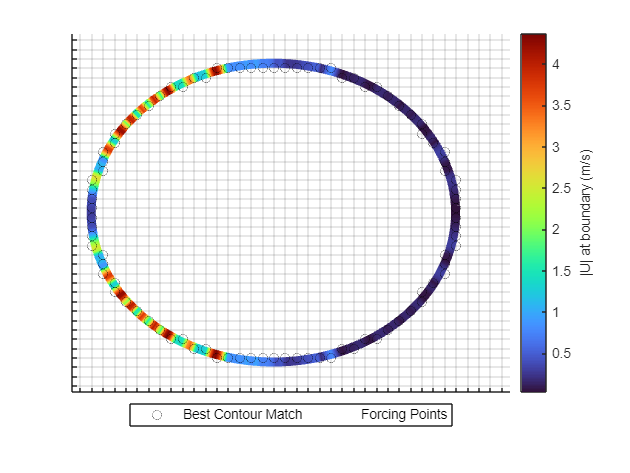

hold off

#### Boundary Layer (flat plate):


% % Characteristic length (chord / plate length)
% c = max(xGeo) - min(xGeo);
% 
% % Convert to physical x locations
% xTargets = min(xGeo) + xOverC * c;
% 
% % Storage structure
% BL = struct();
% 
% figure; hold on;
% 
% for i = 1:length(xTargets)
% 
%     %  Find closest x location in grid 
%     [~, idx] = min(abs(X(1,:) - xTargets(i)));
% 
%     %  Extract vertical profile 
%     x_line = X(:, idx);
%     y_line = Y(:, idx);
%     u_line = u(:, idx);
% 
%     %  Sort by y (important for profiles) 
%     [y_sorted, sortIdx] = sort(y_line);
%     u_sorted = u_line(sortIdx);
% 
%     %  Remove NaNs 
%     valid = ~isnan(u_sorted);
%     y_sorted = y_sorted(valid);
%     u_sorted = u_sorted(valid);
% 
%     %  Normalize velocity using freestream 
%     u_norm = u_sorted / U0;
% 
%     %  Store data 
%     BL(i).xOverC = xOverC(i);
%     BL(i).x = xTargets(i);
%     BL(i).y = y_sorted;
%     BL(i).u = u_sorted;
%     BL(i).u_norm = u_norm;
% 
%     %  Plot 
%     plot(u_norm, y_sorted, 'LineWidth', 1.5, ...
%         'DisplayName', sprintf('x/c = %.2f', xOverC(i)));
% end
% 
% xlabel('u / U_\infty');
% ylabel('y');
% title('Boundary Layer Velocity Profiles');
% legend show;
% grid on;


#### Boundary Layer (General):

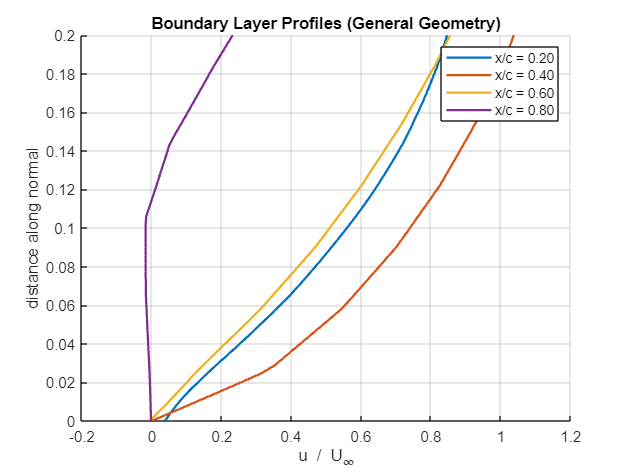

%%  BOUNDARY LAYER PROFILES (GENERAL GEOMETRY) 

% Characteristic length (chord / plate length)
c = max(xGeo) - min(xGeo);

% Define x/c locations
xOverC = [0.2, 0.4, 0.6, 0.8];

% Example surface points (can be anywhere)
xSurf = xOverC * c + min(xGeo);   % x locations
[xGeo_unique, idx_unique] = unique(xGeo);
yGeo_unique = yGeo(idx_unique);
ySurf = interp1(xGeo_unique, yGeo_unique, xSurf);
nPoints = 50;                                % points along normal
normalLength = 0.2 * c;                     % max distance along normal

% Storage
BL_general = struct();
figure; hold on;

for i = 1:length(xSurf)
    
    %  Approximate local tangent 
    [~, idxGeo] = min(abs(xGeo - xSurf(i)));
    if idxGeo == 1
        dx = xGeo(idxGeo+1) - xGeo(idxGeo);
        dy = yGeo(idxGeo+1) - yGeo(idxGeo);
    else
        dx = xGeo(idxGeo) - xGeo(idxGeo-1);
        dy = yGeo(idxGeo) - yGeo(idxGeo-1);
    end
    tangent = [dx, dy] / norm([dx, dy]);
    
    %  Normal pointing outward (toward fluid) 
    center_x = mean(xGeo); center_y = mean(yGeo);
    normal = [xSurf(i) - center_x, ySurf(i) - center_y]; 
    normal = normal / norm(normal);  % unit vector
    
    %  Points along normal 
    s = linspace(0, normalLength, nPoints);
    x_line = xSurf(i) + normal(1) * s;
    y_line = ySurf(i) + normal(2) * s;
    
    %  Interpolate velocity along normal 
    u_line = interp2(X, Y, u_avg, x_line, y_line);
    u_norm = u_line / U0;
    
    %  Flip normal if velocity decreases along normal 
    if u_norm(1) > u_norm(end)
        normal = -normal;
        x_line = xSurf(i) + normal(1) * s;
        y_line = ySurf(i) + normal(2) * s;
        u_line = interp2(X, Y, u_avg, x_line, y_line);
        u_norm = u_line / U0;
    end
    
    %  Store 
    BL_general(i).xSurf = xSurf(i);
    BL_general(i).ySurf = ySurf(i);
    BL_general(i).x_line = x_line;
    BL_general(i).y_line = y_line;
    BL_general(i).u_line = u_line;
    BL_general(i).u_norm = u_norm;
    
    %  Plot 
    plot(u_norm, s, 'LineWidth', 1.5, 'DisplayName', sprintf('x/c = %.2f', xOverC(i)));
end

xlabel('u / U_\infty'); ylabel('distance along normal'); title('Boundary Layer Profiles (General Geometry)'); legend show; grid on;

#### Plot BL profiles over geometry (WIP):

% %  PLOT VELOCITY PROFILES OVER GEOMETRY 
% 
% figure; hold on; axis equal;
% 
% % Plot geometry
% plot(xGeo, yGeo, 'k-', 'LineWidth', 2, 'DisplayName', 'Geometry');
% 
% % Scaling factor for visualization
% scale = 2000 * c;  % how far to extend profiles in x/y for plotting
% 
% % Loop over all profiles
% for i = 1:length(BL_general)
% 
%     % Extract normal vector for plotting
%     xSurf_i = BL_general(i).xSurf;
%     ySurf_i = BL_general(i).ySurf;
%     x_line = BL_general(i).x_line;
%     y_line = BL_general(i).y_line;
%     u_norm = BL_general(i).u_norm;
% 
%     % Vector along normal scaled by velocity
%     x_plot = xSurf_i + (x_line - xSurf_i) .* u_norm * scale;
%     y_plot = ySurf_i + (y_line - ySurf_i) .* u_norm * scale;
% 
%     % Plot profile
%     plot(x_plot, y_plot, 'LineWidth', 1.5, 'DisplayName', sprintf('x/c = %.2f', xOverC));
% end
% 
% xlabel('X'); ylabel('Y');
% title('Boundary Layer Profiles over Geometry');
% legend('Geometry',['x/c = ' num2str(xOverC(1))], ['x/c = ' num2str(xOverC(2))], ['x/c = ' num2str(xOverC(3))], ['x/c = ' num2str(xOverC(4))], "Location", "eastoutside");
% grid on;
